# TP 1 : Spectral characterization 

## I. Frequency filtering  

1)

img = imread('TP01I01.jpg');
figure(1);
subplot(1,3,1);
imshow(img);
img_d=double(img);


colormap(gray(256));
f_spectrum = fftshift(fft2(img));
subplot(1,3,2);
imagesc(log(abs(f_spectrum)));

2)

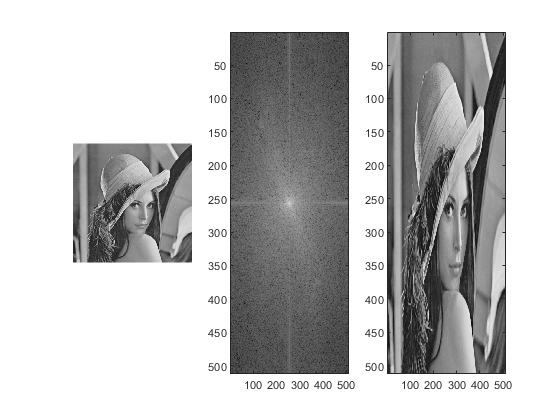

img_inv_f_spectrum= abs(ifft2(fftshift(f_spectrum)));
subplot(1,3,3);
imagesc(img_inv_f_spectrum);


rmse = immse(img_d, img_inv_f_spectrum)

rmse = 2.8775e-28

3)

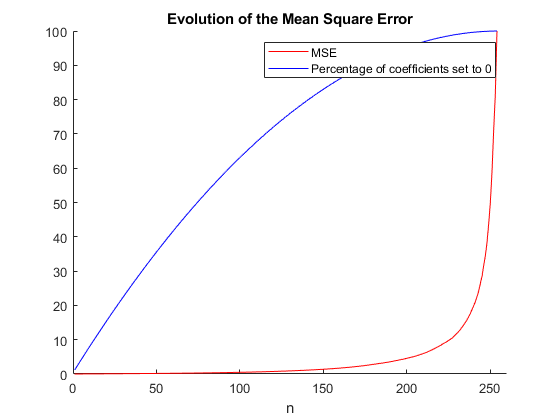

n=1;
n_tot=[];
nb_zeros=[];
nb_zero_tot=0;
error=[];
f_spectrum2=f_spectrum;
longueur_image = size(img_d,1);
largeur_image = size(img_d,2);

while (n < largeur_image/2-1)
            f_spectrum2(1:n,:)=0;
            f_spectrum2(longueur_image-n:longueur_image,:)=0;
            f_spectrum2(:,1:n)=0;
            f_spectrum2(:,largeur_image-n:largeur_image)=0;
            img_filtered = abs(ifft2(fftshift(f_spectrum2)));
            rmse = immse(img_d, img_filtered) ;
            error = [error rmse];
            nbr_zeros = length(find(f_spectrum2==0));
            nb_zeros=[nb_zeros nbr_zeros];
            n_tot=[n_tot n];
            n=n+1;
            
end
%Mise en pourcentage
max_error=max(error);
error_pct=(error/max_error)*100;
nb_zeros_pct=(nb_zeros/max(nb_zeros))*100;
figure(2);
hold on;
plot (n_tot,error_pct,'r');
plot (n_tot,nb_zeros_pct,'b');
hold off;
title("Evolution of the Mean Square Error")
legend('MSE','Percentage of coefficients set to 0')
xlabel('n') 
axis([0 n+5 0 100]);

## II Characterization

1)